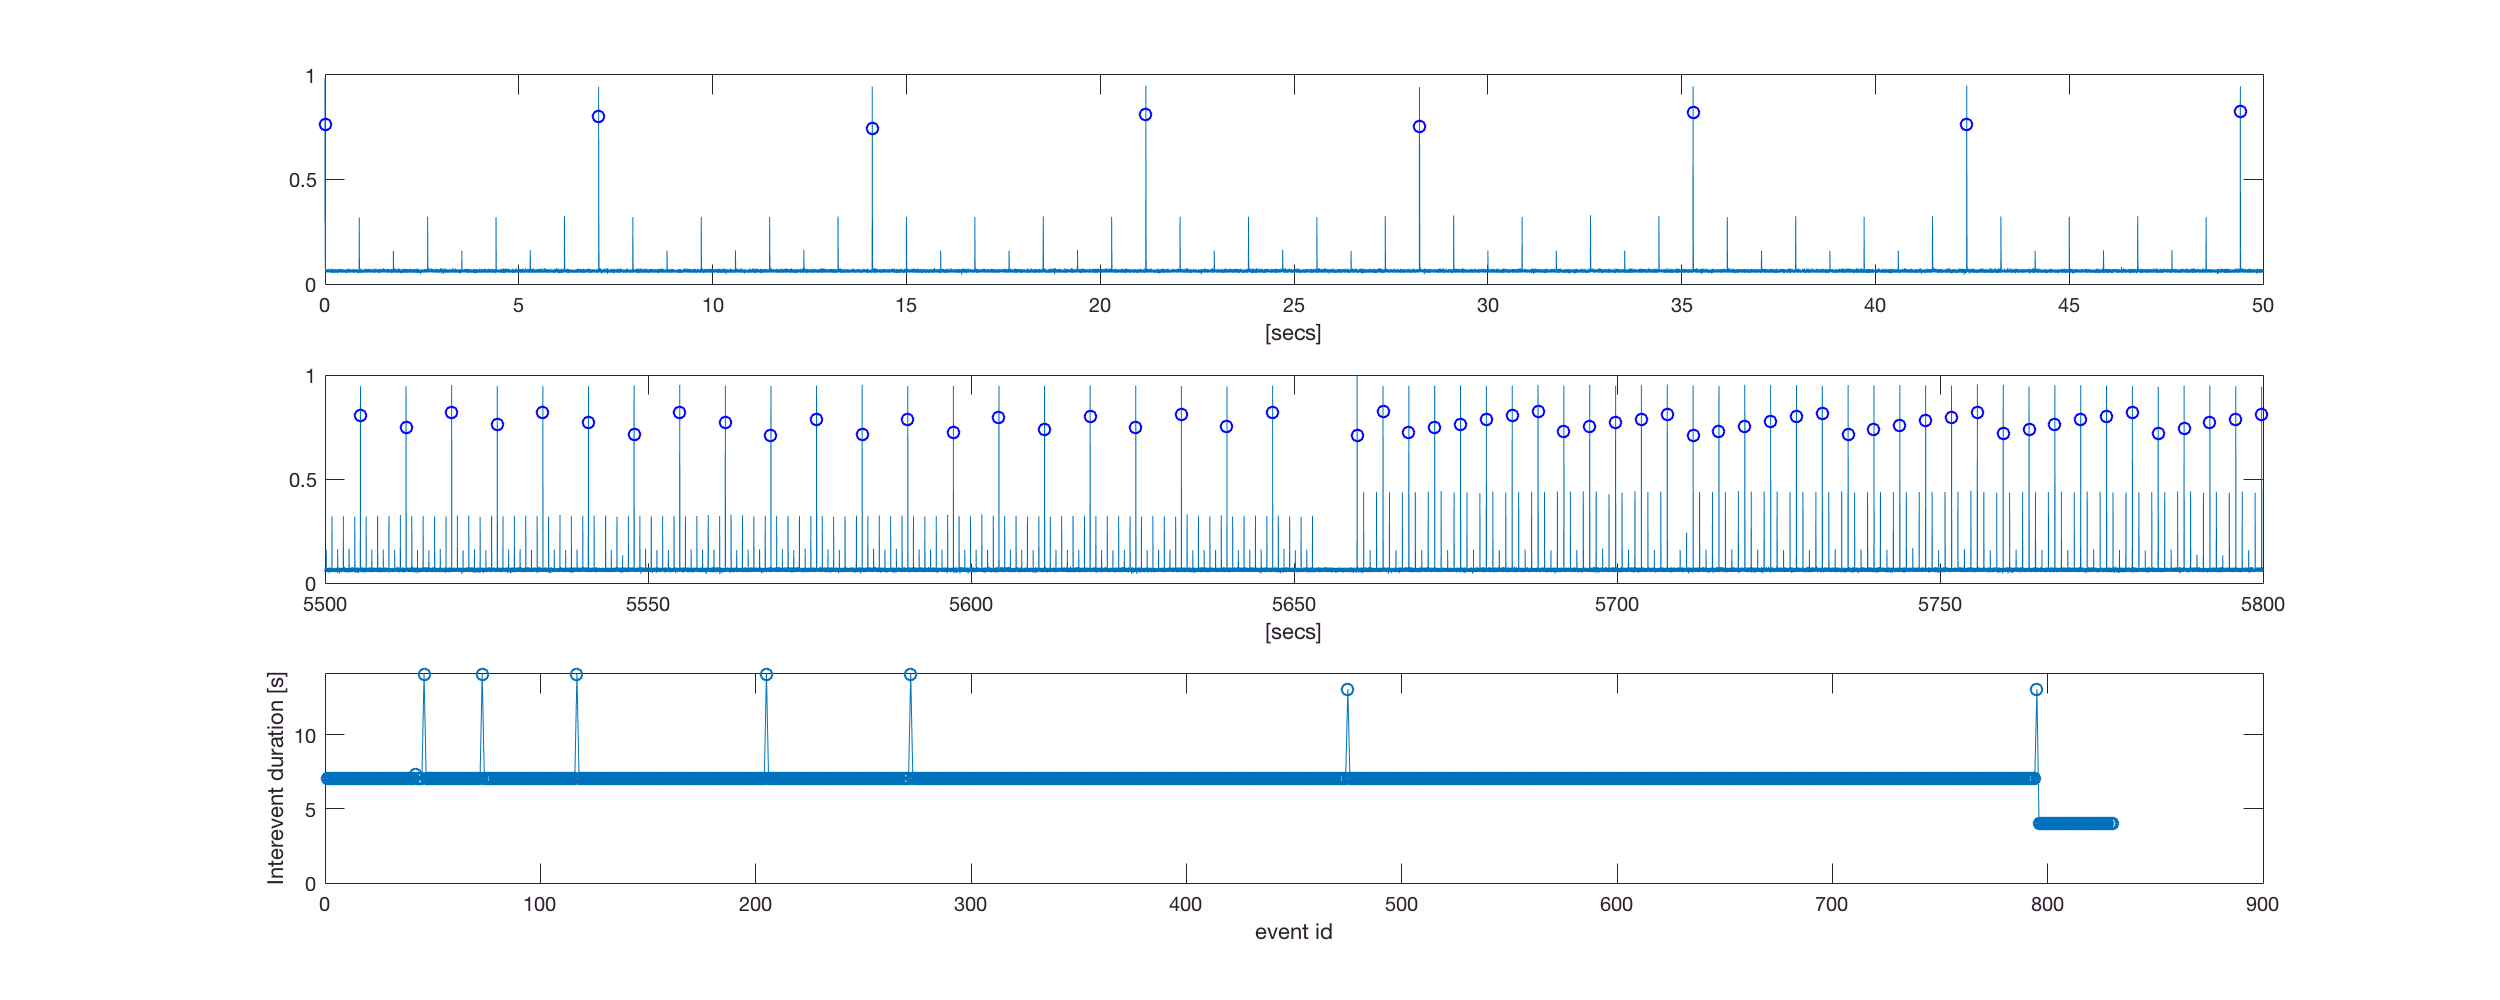

% struct g after sorting
% spikes from i-th file (experiment) and align the timestamps of 'all' cells relative to events.
% PD should provide timings of the events.
cd('/Users/peterfish/Documents/1__Retina_Study/DATA_2016/16-10-31');
%
[pd, ev_id, srate] = getpd('1031drift.h5');

save('pd.mat', 'pd');
load('16-10-31.mat');

cd('/Users/peterfish/Documents/1__Retina_Study/DATA_2016/16-10-31');
load('16-10-31.mat');
if ~exist('pd')
    load('pd.mat');
end

## File ID (Experiment ID)

i_file = 1; % file id (experiment id)

## Spike timestamps of j-th cell and Align relative to trigger signals (PD)

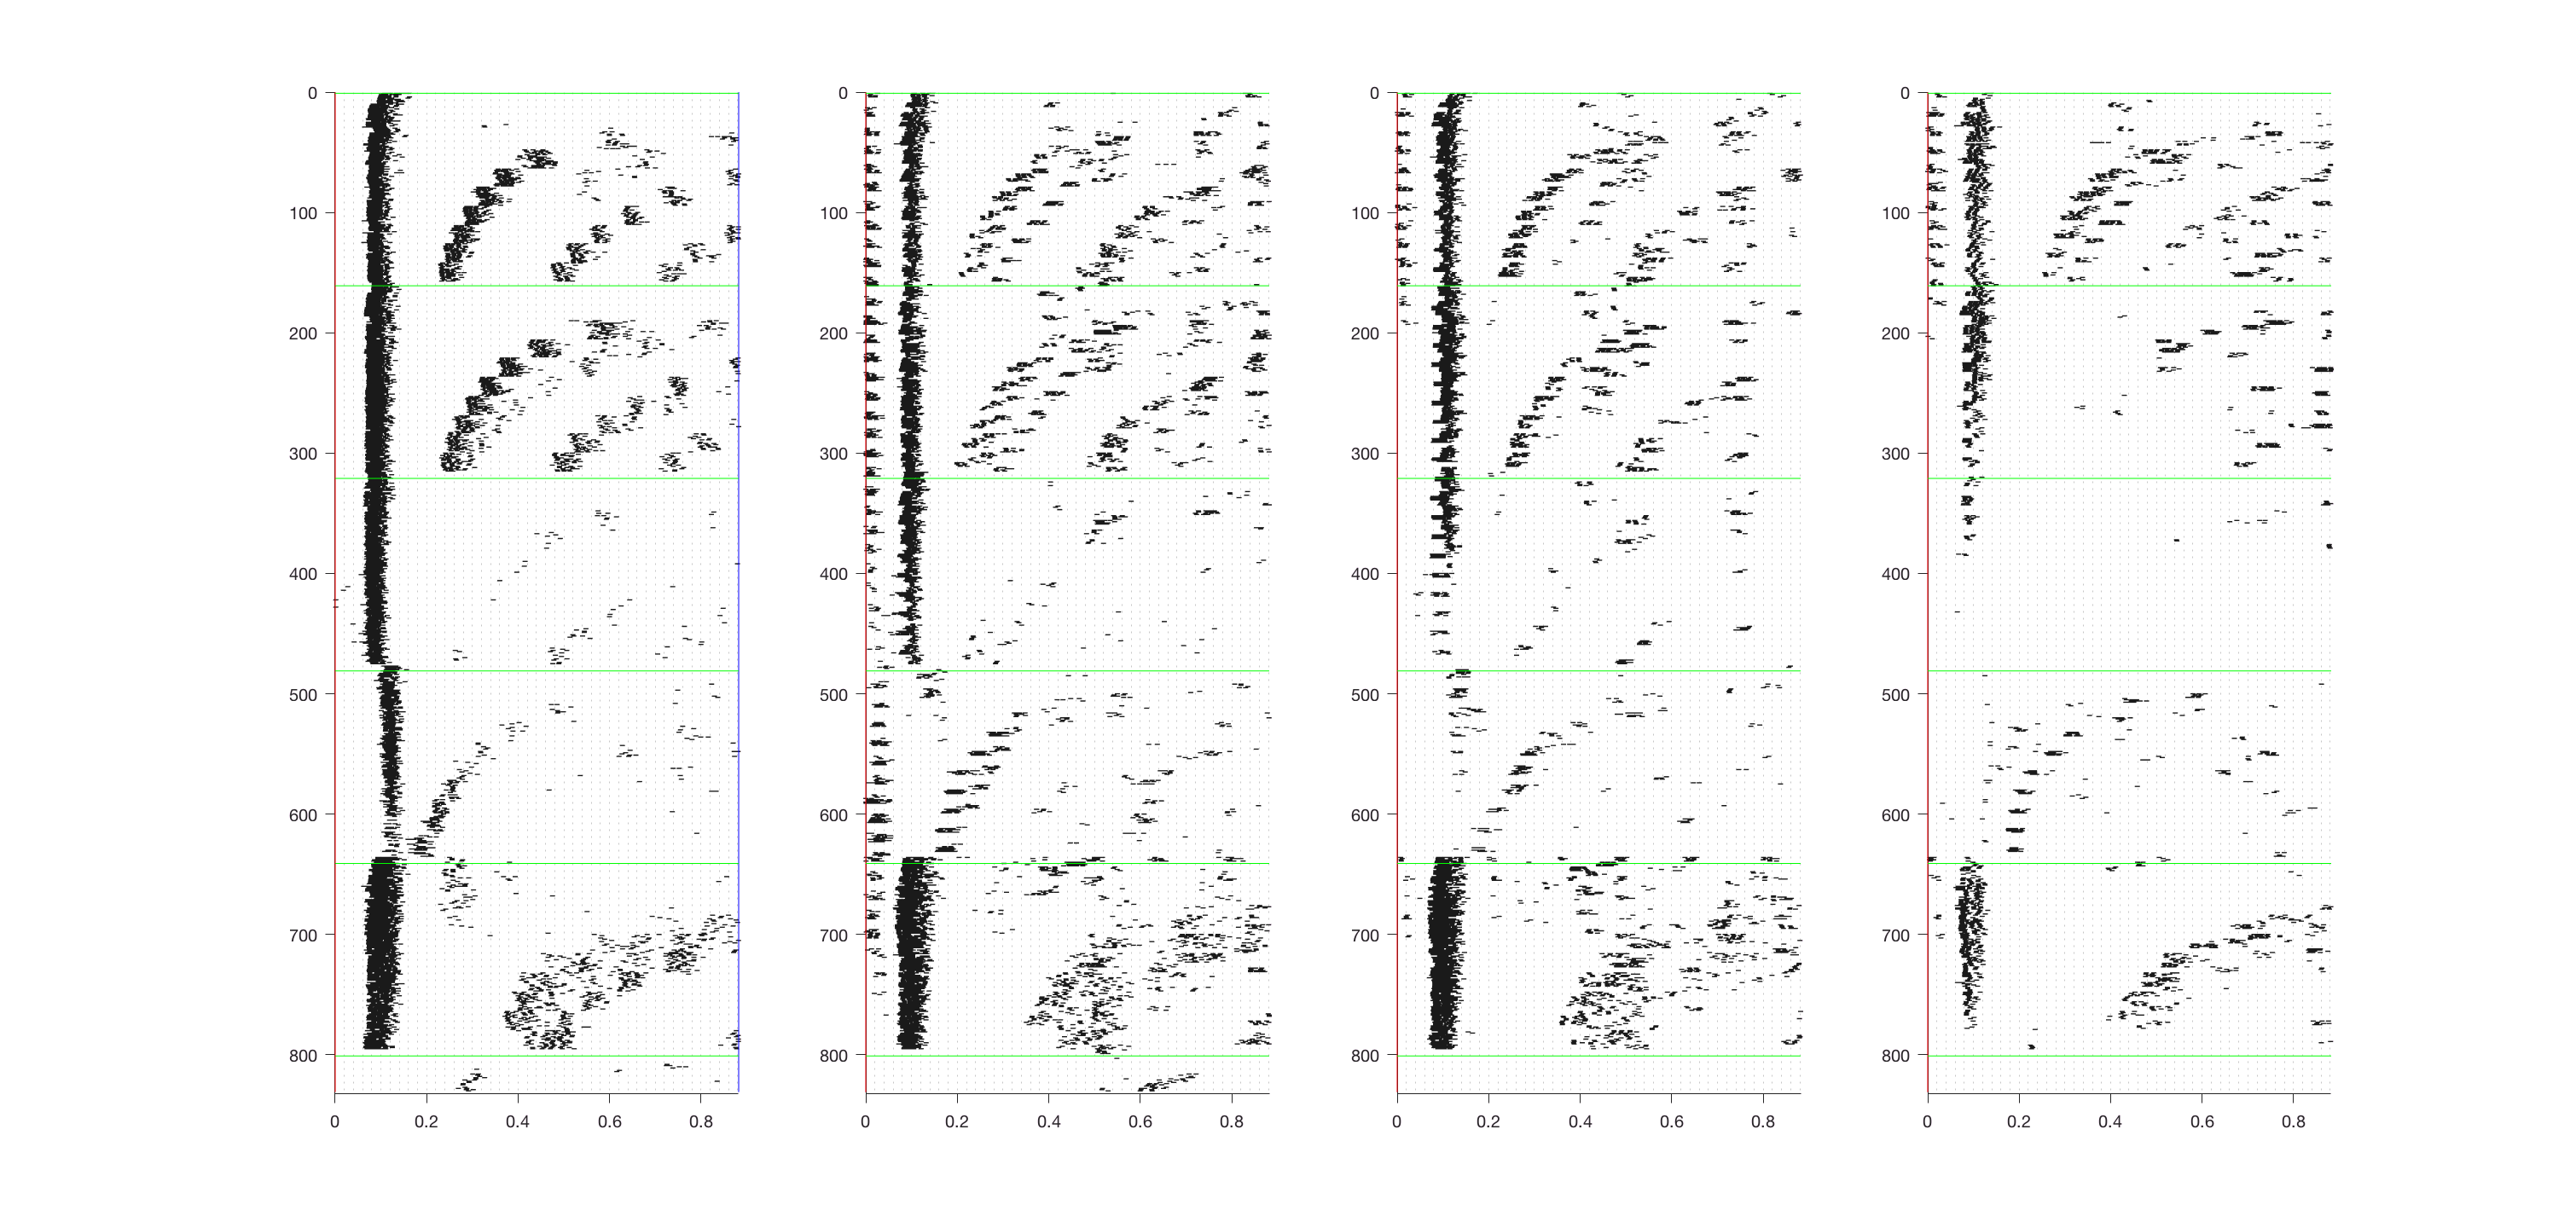

j_cell = 6; % cell id

% Aligned spikes from i-th file (experiment) 
spikes = after_sorting(g, pd, i_file);
% Full view
%figure; myraster(spikes{j_cell});

% spiit into sessions (& align ts relative to session start)
n_session = 8; 
numframes_session = 75; 
ifi = 0.01176470588;
duration = numframes_session * ifi;
ev = 0:duration:duration*(n_session-1);
%
spikes_session = split_to_event(spikes{j_cell}, ev);
% sessions after transitions
transitions = [2, 4, 6, 8];
n_transitions = length(transitions);
figure;
for i = 1:n_transitions
    subplot(1, n_transitions, i);
    myraster(spikes_session{transitions(i)});
end

## Focus on 'k-th' session 

k_session = 8;
% line range (missing PD signals, order of functions.. )
i_exp = 640; % line id for experiment
n_exp = 160;    % # of lines
trigger_missing = 4;
%
i_exp = i_exp - trigger_missing;
s = spikes_session{k_session}(i_exp:i_exp+n_exp-1);
n_exp = numel(s)

n_exp = 160

! a certain cell does not contain a vector.


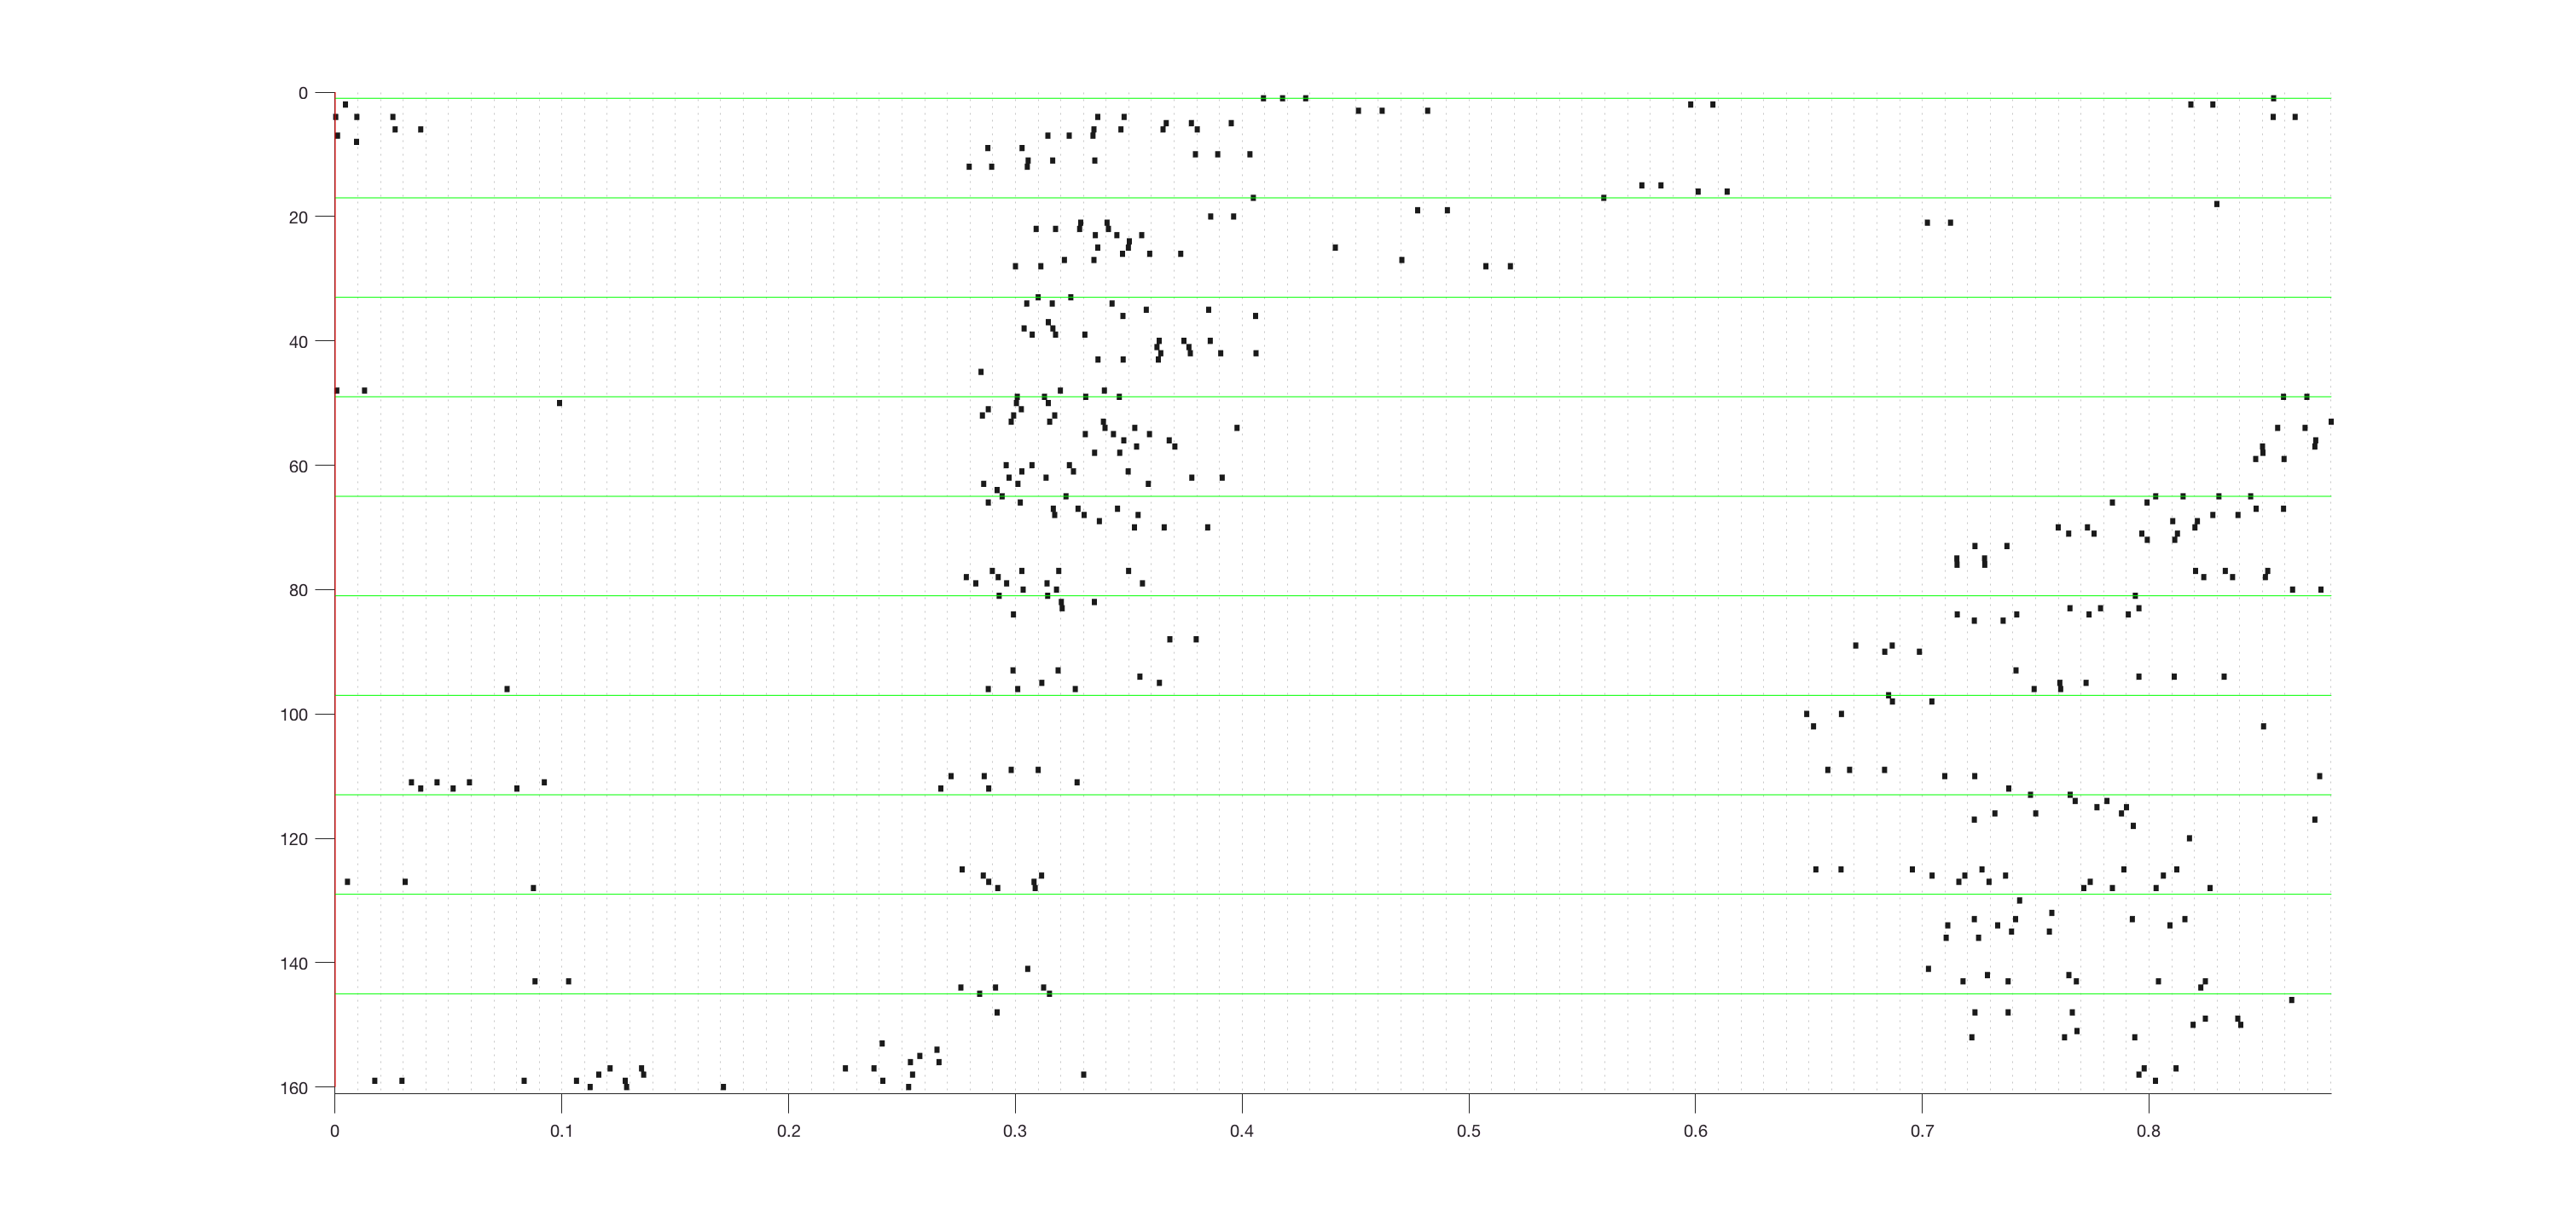

figure; myraster(s, 16);

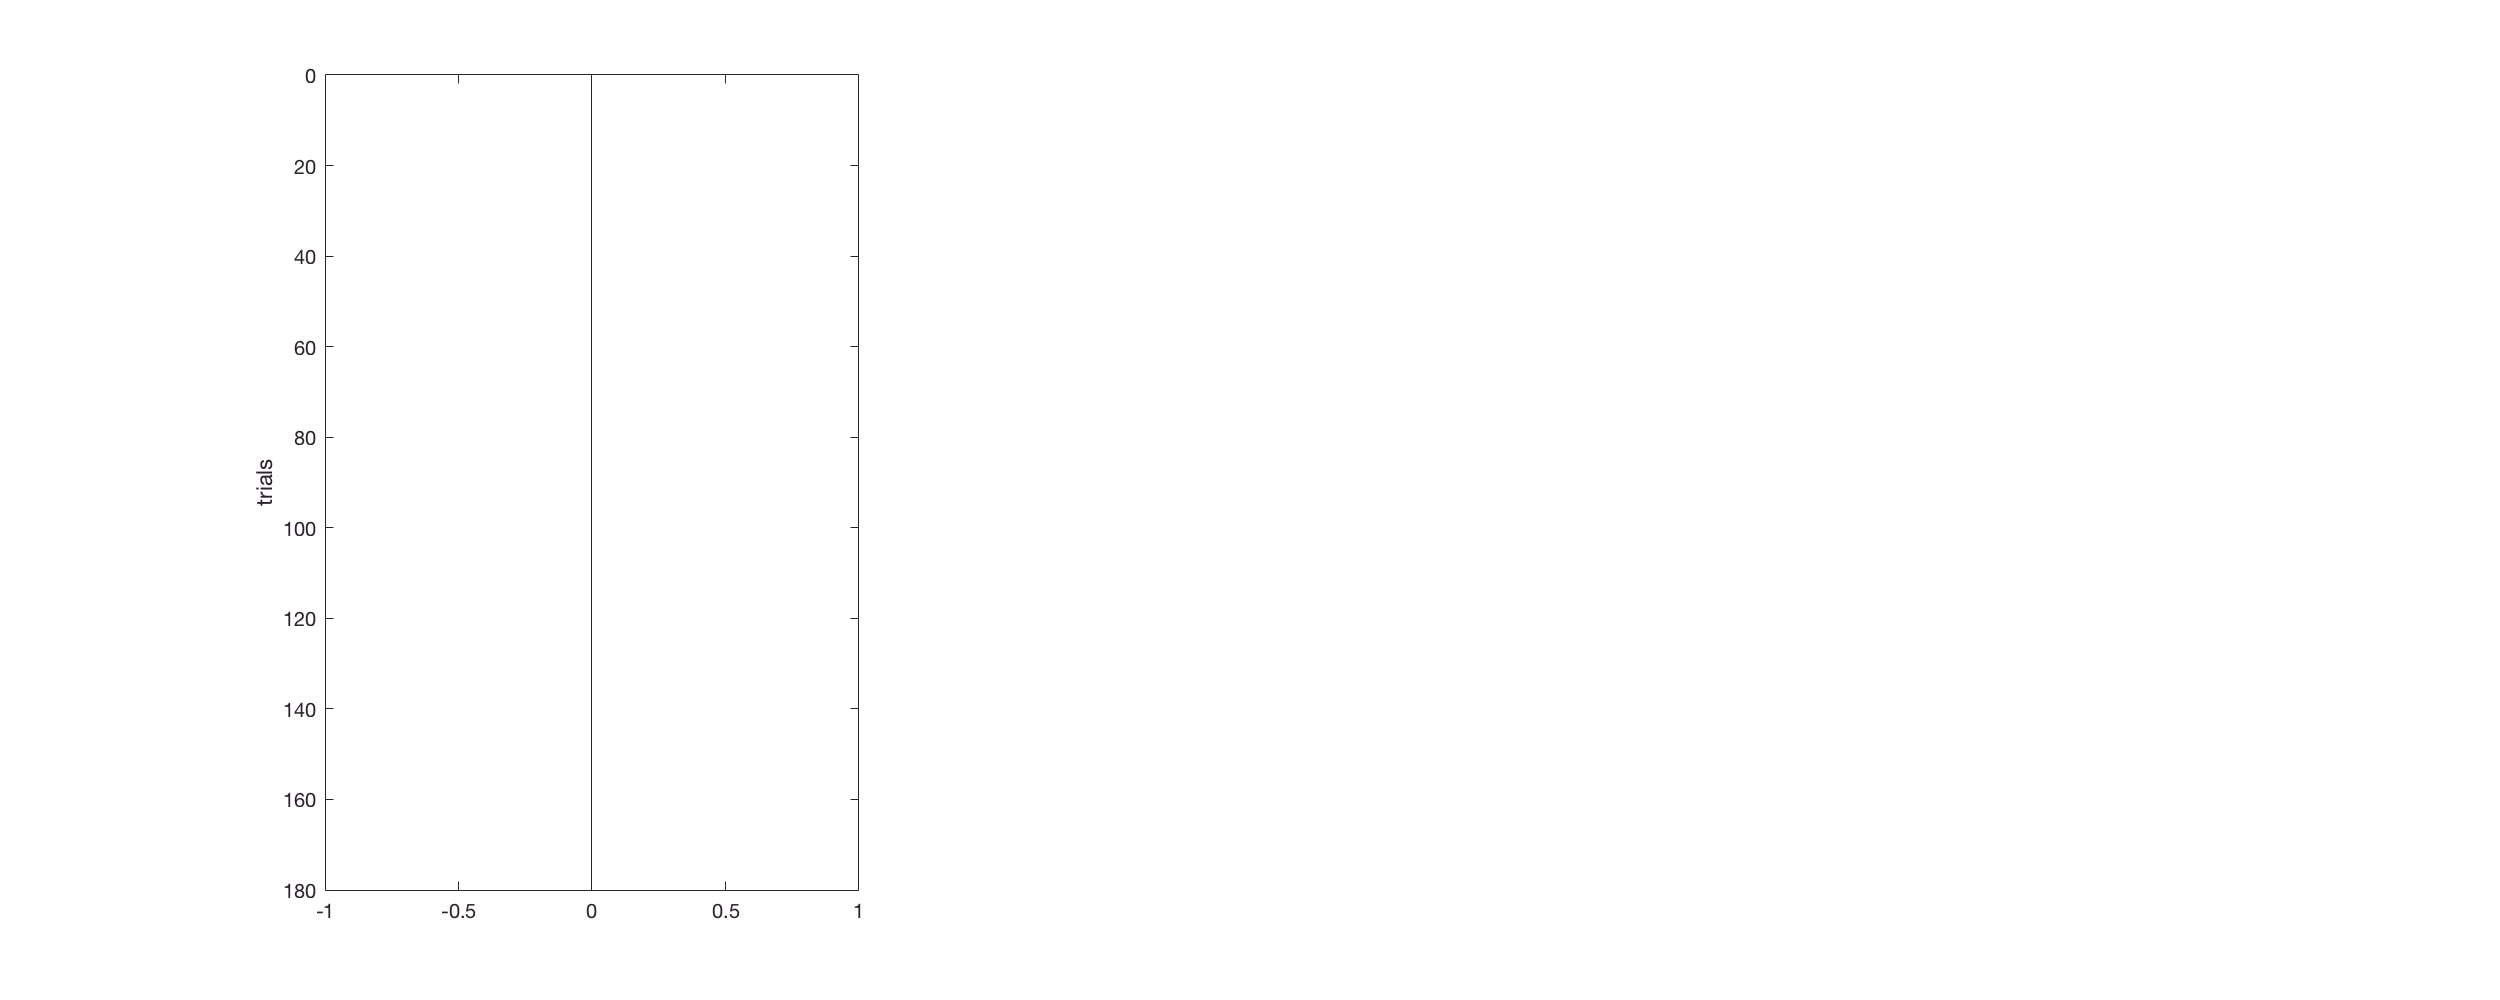

% Choose a window for an analysis
t_window = [0.2 0.6];
t_duration = t_window(2)-t_window(1);

% psth of each row (array)
psth = zeros(n_exp, 1);
firstspike = zeros(n_exp, 1);
% all the experiment
for i = 1:n_exp
    % logical array for time stamps: is it within the time window?
    idx1 = s{i} > t_window(1);
    idx2 = s{i} < t_window(2);
    idx = idx1 & idx2;
    psth(i) = sum(idx); % PSTH of the i-th row (or repeat)
    
    spikes_in_window = s{i}(idx); % can be an array or an empty
    if isempty(spikes_in_window)
        firstspike(i) = NaN;     % cannot be averaged..
    else 
        firstspike(i) = spikes_in_window(1); 
    end
end
% bar graph horizontally
subplot(1, 3, 1);
barh(psth); ylabel('trials');
set(gca,'Ydir','reverse')

## Average every m repeats of 'Timestamps'

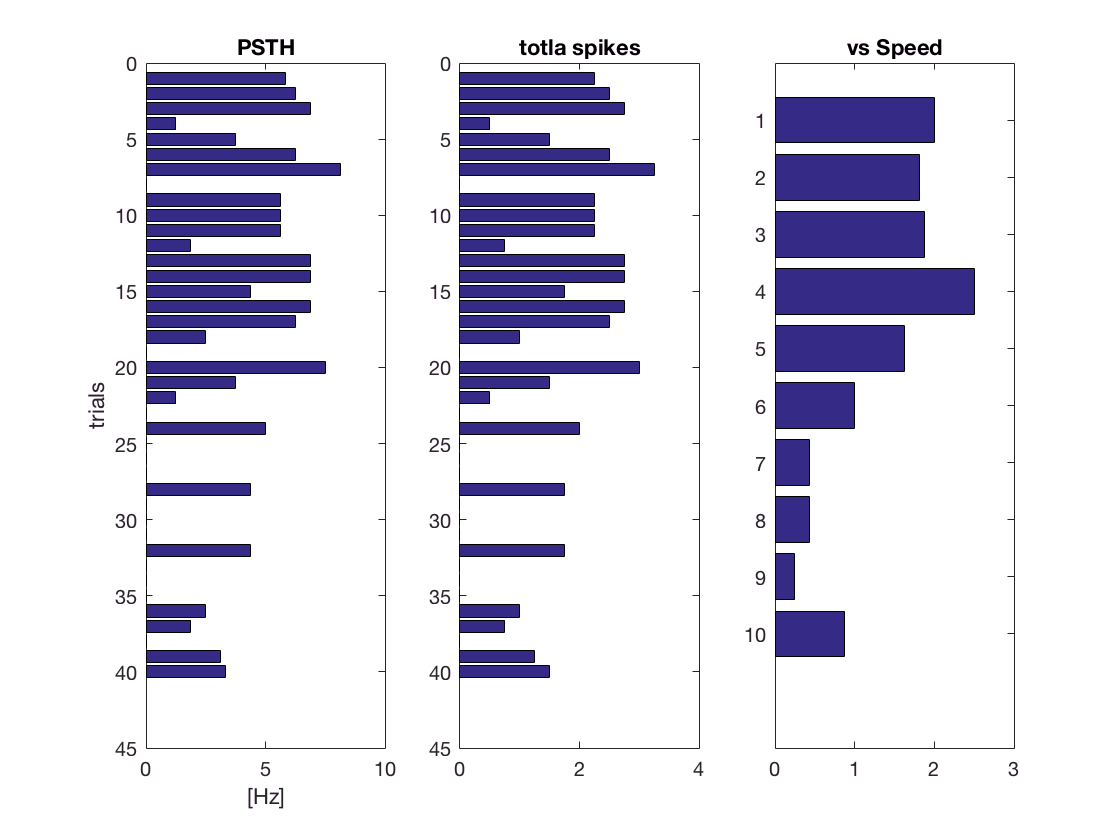

n_repeat = 4;
n_jitter = 4;
%
psth_avg = stat_every(psth, n_repeat);
psth_speed = stat_every(psth_avg, n_jitter);
firstspike_j = stat_every(firstspike, n_repeat);
firstspike_s = stat_every(firstspike_j, n_jitter);
%
subplot(1, 3, 2); barh(psth_avg);   set(gca,'Ydir','reverse'); title('totla spikes');
subplot(1, 3, 3); barh(psth_speed); set(gca,'Ydir','reverse'); title('vs Speed');

## Analysis with 'Firing Rate':

Avg & STD over identical repeats

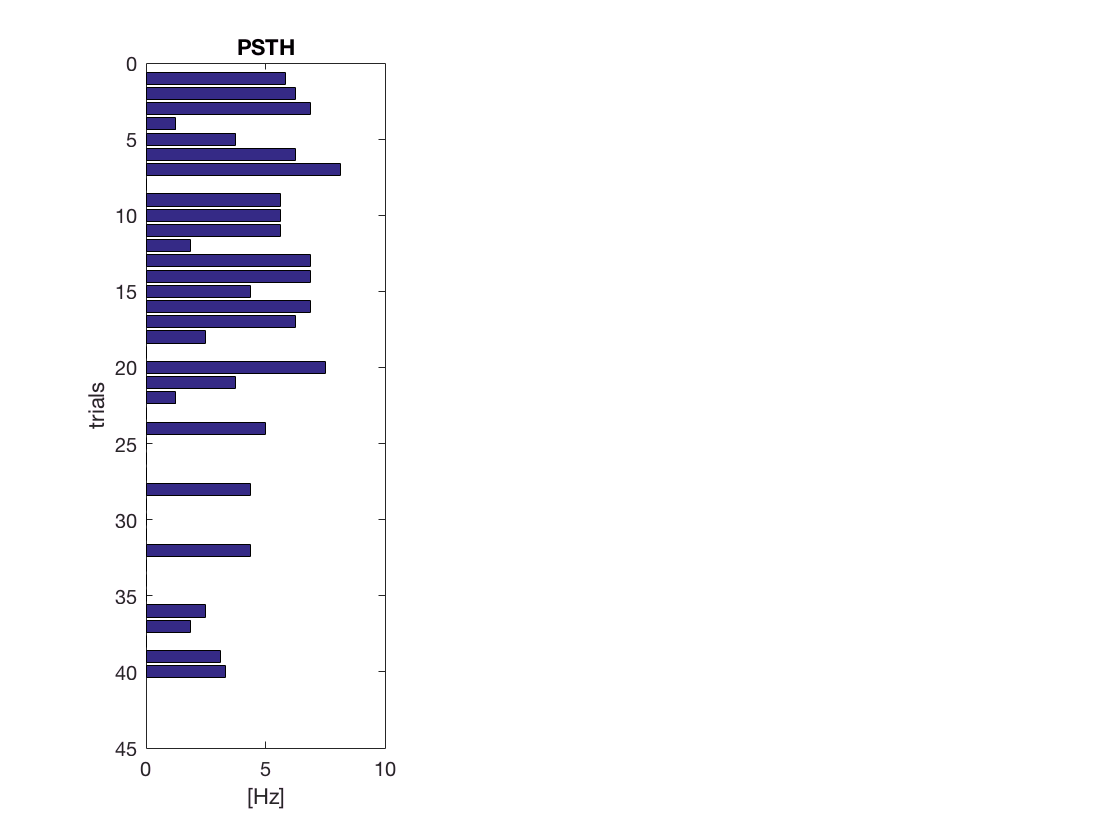

% firing rate (basically, binning & smoothing)
bin_size = 0.02;
smoothing = 3;
rate = ts_rate_cell(s, t_window, bin_size, smoothing); % rate is an array

% average FR over repeats (identical stimulus)
[avg_r, std_r] = stat_every(rate, n_repeat);
% psth over time window
psth_r = mean(avg_r, 2);

figure;
subplot(1, 3, 1); barh(psth_r); title('PSTH'); xlabel('[Hz]'); ylabel('trials'); set(gca,'Ydir','reverse'); 


% peak of smoothed rate & its latency
[peak_r, id_r] = max(avg_r, [], 2);

## Avg & STD over certain conditions (e.g. same speed)

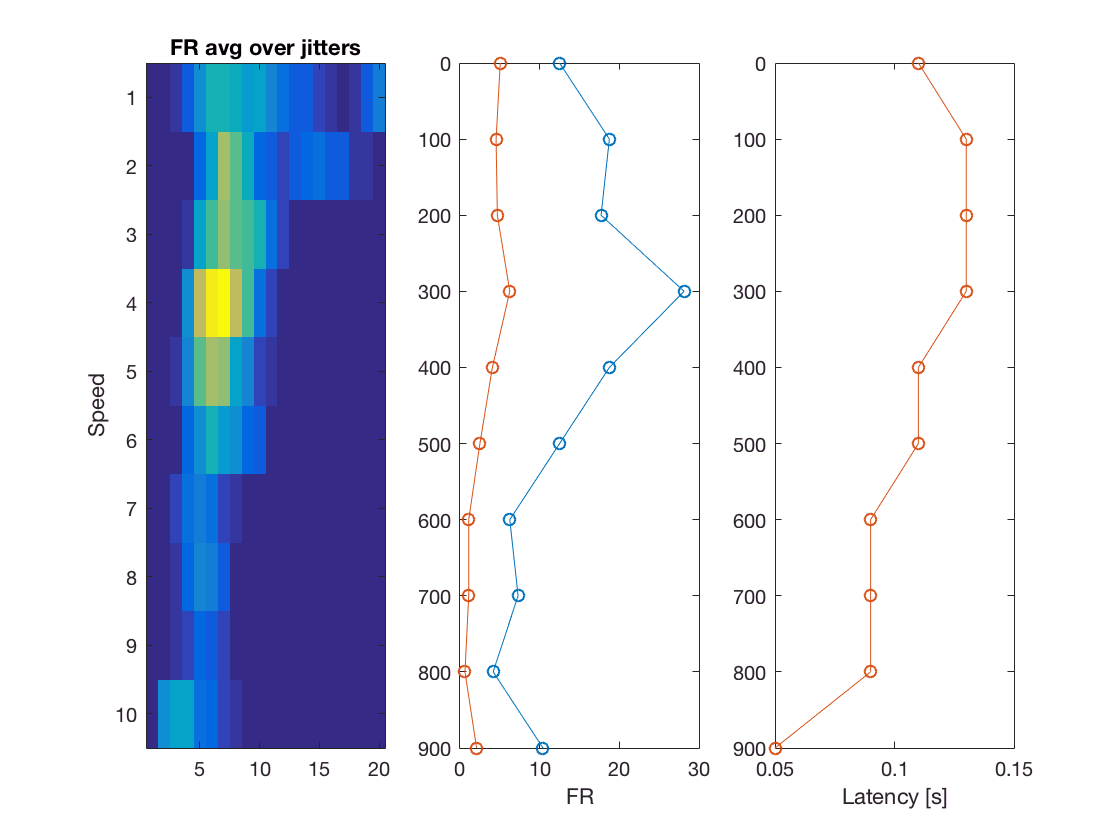

% avg over differnet jitter sequences.
[avg_s, std_s] = stat_every(avg_r, n_jitter);
x_condition = 0:100:900; % final variable of the condition (e.g. speed)

%
[peak_s, id_s] = max(avg_s, [], 2);

% display
figure;
subplot(1,3,1); imagesc(avg_s); title('FR avg over jitters'); ylabel('Speed');
subplot(1,3,2); plot(peak_s, x_condition, 'o-'); hold on; % Peak FR
   plot(mean(avg_s, 2), x_condition, 'o-');   % psth
set(gca,'Ydir','reverse'); xlabel('FR');

subplot(1,3,3); 
%subplot(1,3,3); barh(id_s*bin_size); set(gca,'Ydir','reverse')
plot(firstspike_s, x_condition, 'o-');     hold on;       % latency of the 1st spike
plot((id_s-0.5)*bin_size, x_condition, 'o-'); hold on;    % latency of the peak FR

set(gca,'Ydir','reverse'); xlabel('Latency [s]');

Full view

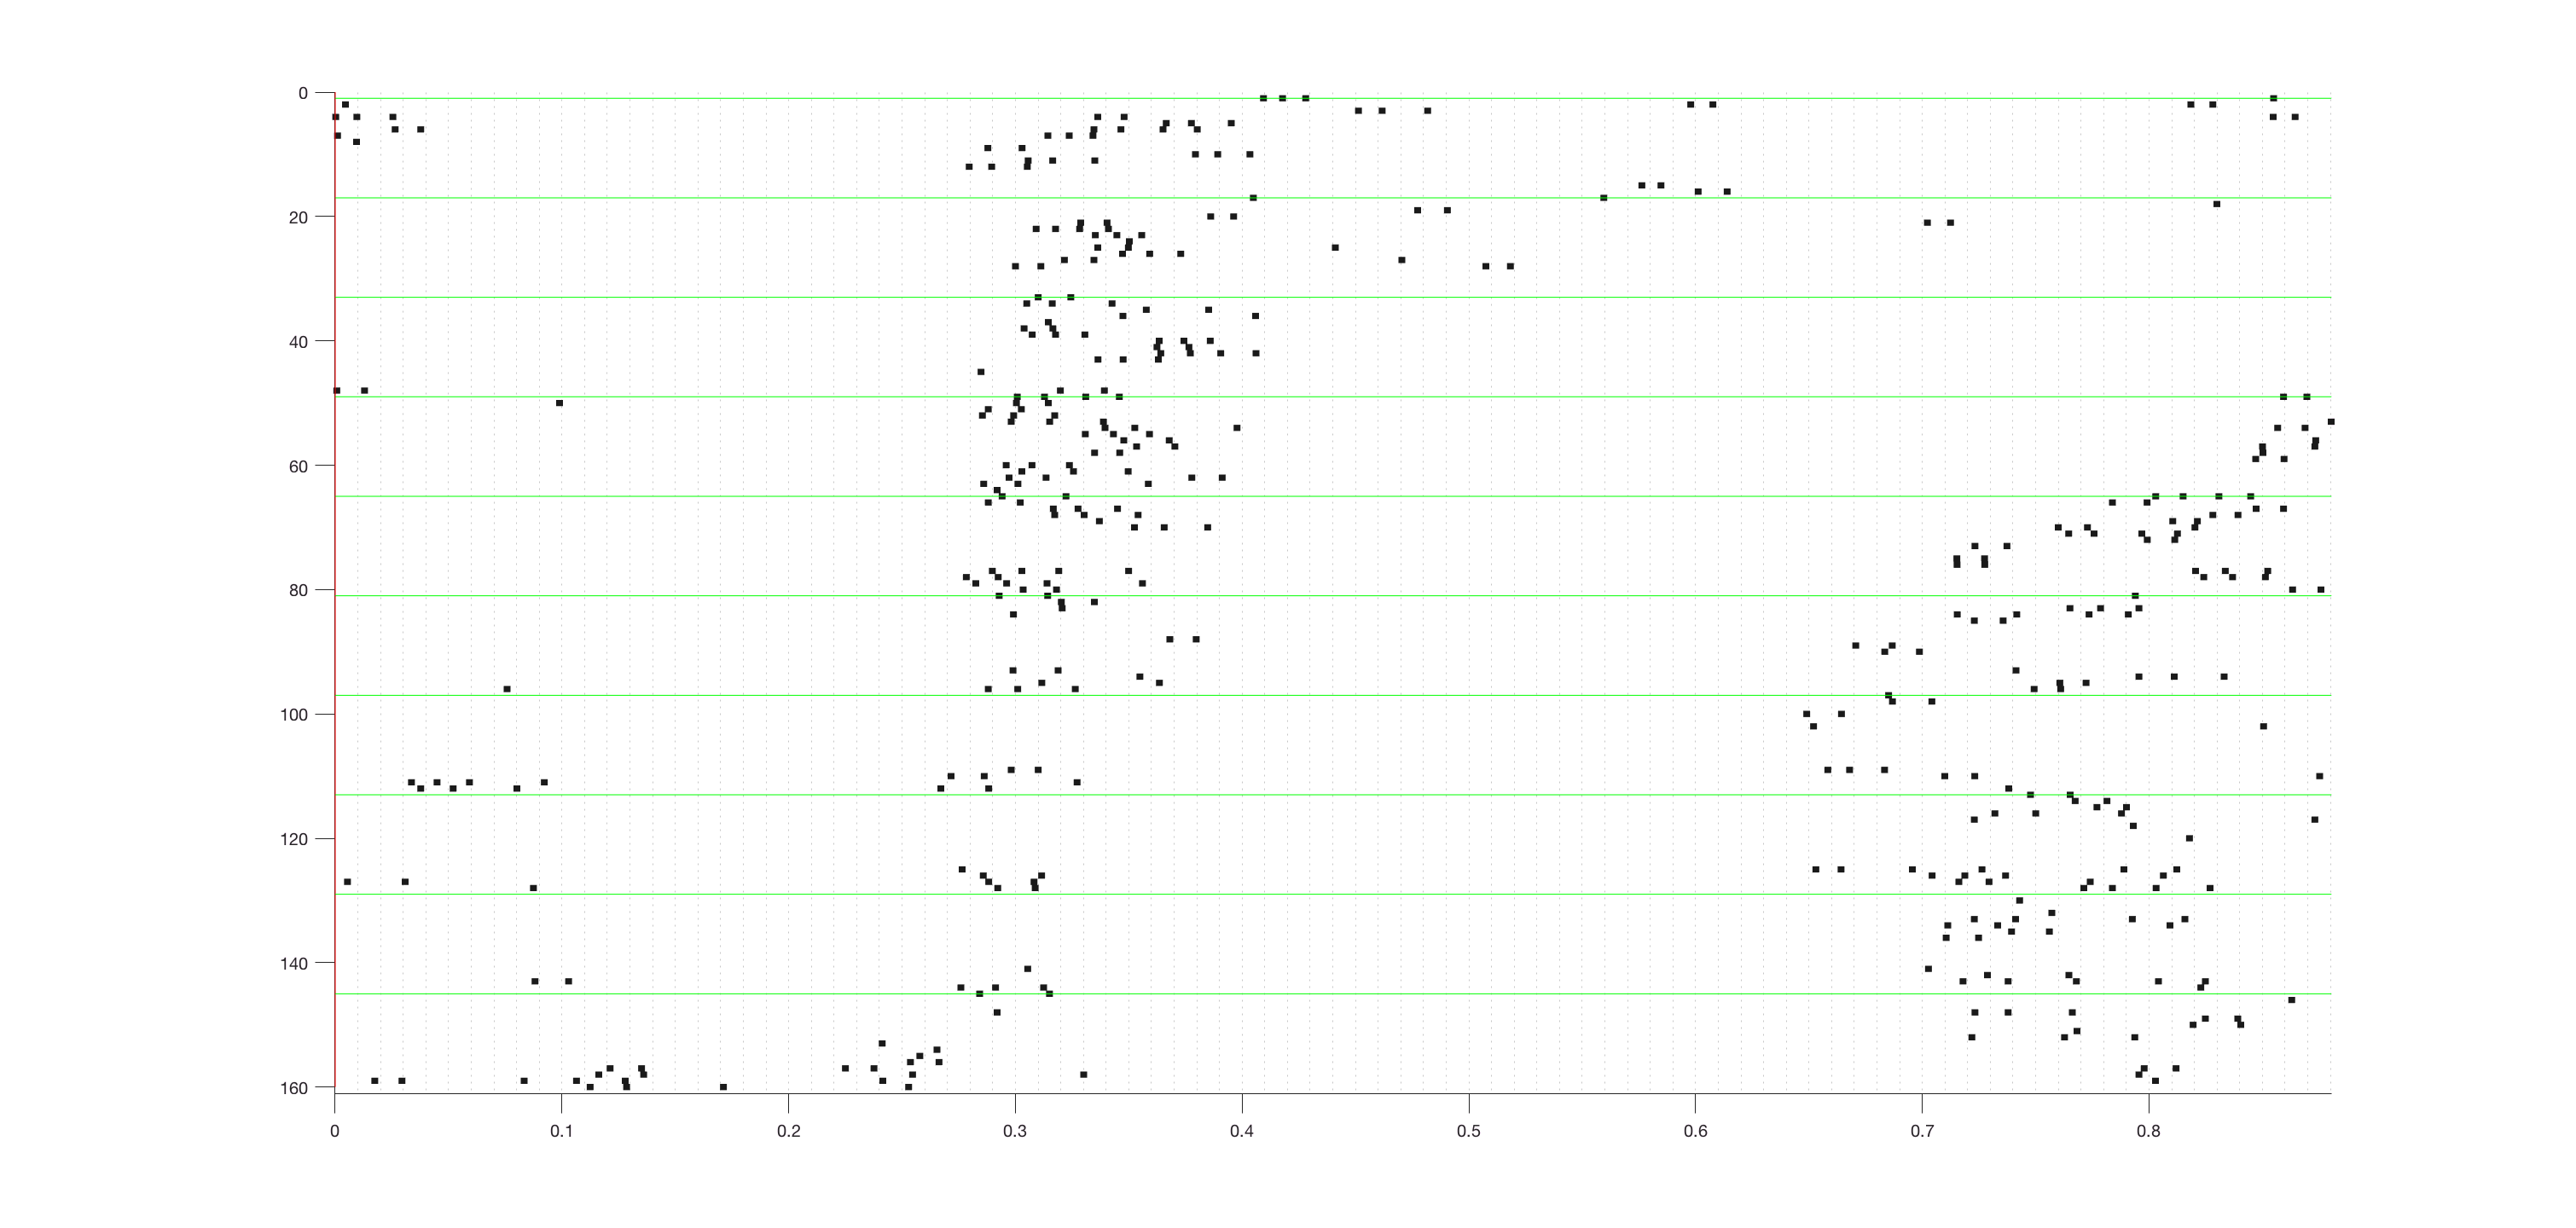

! a certain cell does not contain a vector.
